# INITIAL DATA

clc; clear; close all;

% Saving every pressure trace into a struct
struct = load('tracesbar1.mat');    % Creating the structure [bar]
fn = fieldnames(struct);            % Structure field names
dim = numel(fn);                    % Number of fields

% ENGINE DATA
web = 30;              % web thickness     [mm]
l = 290/1000;          % motor lenght      [m]
Di = 100/1000;         % Internal diameter [m]
De = 160/1000;         % External diameter [m]
Dt_high = 21.81/1000;  % Throat diameter for high pressure   [m]
Dt_mid = 25.26/1000;   % Throat diameter for medium pressure [m]
Dt_low = 28.80/1000;   % Throat diameter for low pressure    [m]

% Avect = (pi/4)*[Dt_high^2; Dt_mid^2; Dt_low^2];   % Throat area vector [m^2]
Avect = (pi/4)*[Dt_low^2; Dt_mid^2; Dt_high^2];     % Throat area vector [m^2]

% PROPELLANT DATA
AP = 68/100;      % Ammonium perchlorate percentage [%]
Al = 18/100;      % Alluminium percentage           [%]
HTPB = 14/100;    % HTPB binder percentage          [%]
rho_AP = 1950;    % Ammonium perchlorate density    [kg/m^3]
rho_Al = 2700;    % Alluminium density              [kg/m^3]
rho_HTPB = 920;   % HTPB binder density             [kg/m^3]

rho_tot = (AP + Al + HTPB)/(AP/rho_AP + Al/rho_Al + HTPB/rho_HTPB);      % Total density of the propellant [kg/m^3]
Mtot = rho_tot*(pi*l*(De^2 - Di^2))/4;                                   % Total mass of the propellant    [kg]

# A) EXPERIMENTAL ANALYSIS

From the data set obtained the main objective is to construct the model to simulate the pressure trace over time: $p(t) = \left( \frac{A_b}{A_t} a \rho_p  C^\ast \right)^{\frac{1}{1-n}}
$

### A0) INITIALIZATION

% Initializing the vectors
Num = dim*size(struct.(fn{1}), 2);   % Number of samples (27 in our case)

Peff = zeros(Num,1);   % Effective pressure vector [bar]
rb = zeros(Num,1);     % Burning rate vector       [mm/s]
Cstar = zeros(Num,1);  % C* vector                 [m/s]
k = 1;                % Index

% For i = 1:9 & for j = 1:3

for i = 1:dim
    for j = 1:size(struct.(fn{i}), 2)
        
        P = struct.(fn{i})(:,j);          % Pressure graph of ith measurement, jth pressure level (high, medium, low)  [bar]
        tvect = ((1:length(P))*0.001)';   % tvect = [0.001 0.002 0.003 ... n] [seconds] ( frequency = 1000Hz ==> dt=1ms )

### A1) DEFINING tA & tG

        [Pmax, ~] = max(filloutliers(P,"next"));   % Maximum pressure encountered in the array [bar]
        P0 = 5/100 * Pmax;                         % Reference pressure to obtain tA and tG    [bar]
        
        [idxA, idxG] = intersections(P, P0);       % Indexes of firtst and last intersection points

### A2) CALCULATING Pref

        I = 1/2 * trapz(tvect(idxA:idxG), P(idxA:idxG));    % Trapezoid method to calculate the area under the curve
        Pref = I/(tvect(idxG)-tvect(idxA));                 % Reference pressure [bar]

### A3) DEFINING tB & tE

        [idxB, idxE] = intersections(P, Pref);    % Indexes of firtst and last intersection points

### A4) CALCULATING THE EFFECTIVE PRESSURE, THE BURNING RATE and C*

        % Calculating the effective pressure
        tburn = tvect(idxE) - tvect(idxB);                           % Burning time [s]
        Peff(k) = 1/tburn * trapz(tvect(idxB:idxE), P(idxB:idxE));   % Effective pressure [bar]

        % Calculating the burning rate
        rb(k) = web/tburn;     % Burning ratio [mm/s] 

        % Calculating C*
        Cstar(k) = trapz(tvect(idxB:idxE), P(idxB:idxE))*(Avect(j)/Mtot)*1e5;   % C* [m/s]

        k = k + 1;
    end
end

### A5) VIEILLE'S LAW PARAMETERS

The Vieille's law parameters are $a\;$& $n$:  $r_b = ap_c^n$

[a, sigma_a, n, sigma_n, R2] = Uncertainty(Peff, rb);
fprintf("The Vieille's law parameters are:\n");

The Vieille's law parameters are:


fprintf("a = %f ± %f  [(mm/s)/bar^n]", a, sigma_a);

a = 1.727076 ± 0.018212  [(mm/s)/bar^n]

fprintf("n = %f ± %f", n, sigma_n);

n = 0.382118 ± 0.002707

### A6) COMPUTATION OF THE MEAN VALUE OF C* & UNCERTAINTY OF THE MEAN VALUE OF C*

$\bar{x} = \frac{1}{n} \sum_{i=1}^{n} x_i
 $    and    $\sigma = \sqrt{\frac{1}{n-1} \sum_{i=1}^{n} (x_i - \bar{x})^2}
$ , $\sigma_{\bar{x}} = \frac{\sigma}{\sqrt{n}}
$.    ==>     $\bar{x} \pm \sigma_{\bar{x}}
$

Cstar_mean = 1/Num * sum(Cstar);                        % Mean value of C*               [m/s]
sigma = sqrt( 1/(Num-1)*sum((Cstar-Cstar_mean).^2) );   % Data set standard deviation    [...]
sigma_Cstar_mean = sigma/sqrt(Num);                     % Standard deviation of the mean [m/s]

fprintf("The mean value of C* and the uncertainty of the mean value are:\n");

The mean value of C* and the uncertainty of the mean value are:


fprintf("C* = %f ± %f   [m/s]", Cstar_mean, sigma_Cstar_mean);

C* = 1517.227719 ± 23.630098   [m/s]

# B) MONTE CARLO ANALYSIS

Once we define the theoretical model we let its parameter vary, picking them randomly from a normal distribution, to obtain different pressure traces and consequently different burning times. Once we obatin the burning times associated to the pressure traces we have to construct the mu and the sigma of tb, letting the montecarlo analysis converge. 

### B1) THEORETICAL MODEL

The theoretical model is: $p(t) = \left( \frac{A_b}{A_t} a \rho_p  C^\ast \right)^{\frac{1}{1-n}}
$, where $A_b =A_b \left(t\right)=2\pi \left(R_{\int } +{a\cdot p\left(t\right)}^n \cdot t\right)\left(l_0 -2{\cdot a\cdot p\left(t\right)}^n \cdot t\right)-2\pi \left\lbrack R_{\textrm{ext}}^2 -{\left(R_{\int } +{a\cdot p\left(t\right)}^n \cdot t\right)}^2 \right\rbrack$

### B2) LETTING $a,n,C^*$ VARY RANDOMLY "N" TIMES, PICKING THEM FROM A GAUSSIAN DISTRIBUTION

Since $a~N\left(\mu_a ,\sigma_a \right)\;\;\;\;\;n~N\left(\mu_n ,\sigma_n \right)\;\;\;\;\;C^* ~N\left(\mu_{C^* } ,\sigma_{C^* } \right),$ every parameter is picked randomly from its own normal distribution.

% % Selecting the number of Monte Carlo simulations 
N = 15;

% Vector of randomly selected parameters
a_samples = normrnd(a, sigma_a, [N, 1]);                        % Vieille's law pre-exponent    [(mm/s)/bar^n]  
n_samples = normrnd(n, sigma_n, [N, 1]);                        % Vieille's law exponent vector [-]
Cstar_samples = normrnd(Cstar_mean, sigma_Cstar_mean, [N, 1]);  % C star vector                 [m/s]

% Creating the matrix containing all the possible permutations
comb = cell(1, 3);
[comb{:}] = ndgrid(1:N);
comb = reshape(cat(3+1, comb{:}), [], 3);

% Shuffling the matrix
comb = comb(randperm(N^3),:);

### B3) MONTE CARLO SIMULATION

In this step we let every parameter vary N times in the ballistic equation. The parameters are being varied in the order specified in the "comb" combination/permutation matrix, where the first column is associated to the a's, the second column is associated to the n's and the third column is associated to the Cstar's.

For every variation of the triplette $\left(a,n,C^* \right)$, the pressure trace is computed and the corresponding burning time is also calculated. At the end of the process we'll get a vector of $N^3$ burning times.Every burning time is associated with an unique triplette$\left(a_x ,n_y ,C_z^* \right),\textrm{where}\;x,y,z\in \left\lbrack 1,N\right\rbrack$, $a_x ,n_y ,C_z^* \;$are extracted from the corresponding shuffled sample vector.

At = pi*(0.0144)^2;  % Throat area         [m^2]
t = 0.001;           % Time step           [s]
Re = De/2;           % External radius     [m]
tb = zeros(N^3, 1);  % Burning time vector [s]
idx = 1;             % Burning time vector index

tic
% NEEDED A CONDITION TO EXIT THE FOR WHEN A TOLLERANCE IS MET. IT'S ALSO POSSIBLE TO USE "parfor" TO SPEED UP THE SIMULATION
for i = 1:N^3

    % Picking the parameters following the random permutations order
    a = a_samples(comb(i,1));
    n = n_samples(comb(i,2));
    Cstar = Cstar_samples(comb(i,3));

    % While loop parameters (Initial conditions)
    Ri = Di/2;   % Initial internal propellant radius [m]
    Lp = l;      % Initial internal propellant length [m]
    q = 0;       % Time index - parameter that keeps track of the time spent in the loop

    while (Ri<Re && Lp>0 )
        Ab = 2*pi*Ri*Lp + 2*pi*(Re^2 - Ri^2);    
        p = ( Ab/At * Cstar * rho_tot * (a/1000)/(1e5^n) )^(1/(1-n));   % Istantaneous pressure [Pa]
    
        rb = (a/1000)*(p/1e5)^n;   % Updating the burning rate  [m/s]   
    
        Ri = Ri + rb*t;       % Updating the propellant radius  [m]
        Lp = Lp - 2*rb*t;     % Updating the propellant length  [m]
        q = q + 1;            % Updating the time index
    end
    
    tb(idx) = (q-1)*t;   % Burning time [s]
    idx = idx + 1;
end
toc

Elapsed time is 5.866192 seconds.


### B4) CONVERGENCE OF MONTE CARLO

We now plot $t_{\textrm{burn}}$ mean value and its variance 

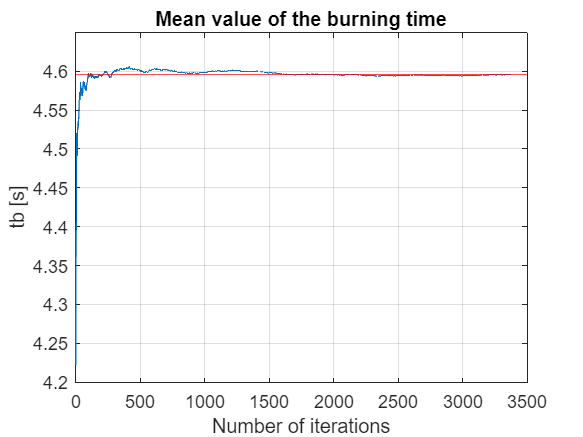

% Checking the mean and the standard variation (of the mean) convergence
mean_vect = zeros(length(tb),1);
sigma_vect = zeros(length(tb),1);

for i = 1:length(tb)
    mean_vect(i) = sum(tb(1:i))/length(tb(1:i));
    if i > 1
        sigma_vect(i) = sqrt( 1/(i-1)*sum((tb(1:i)-mean_vect(i)).^2) );
        % sigma_vect(i) = sigma_vect(i)/sqrt(i);
    end
end

% PLOTTING THE MEAN VALUE BEHAVIOUR
plot(mean_vect);
yline(mean_vect(end), 'Color', 'r');
title("Mean value of the burning time");
xlabel("Number of iterations");
ylabel("tb [s]");
grid on;

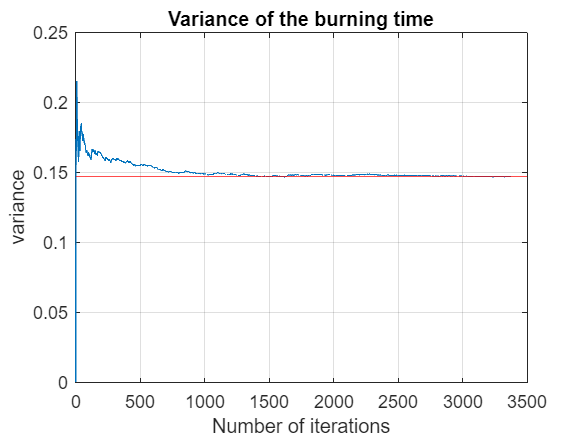


figure;
plot(sigma_vect)
yline(sigma_vect(end), 'Color', 'r');
title("Variance of the burning time");
xlabel("Number of iterations");
ylabel("variance");
grid on;


% sfhffle prima di entrare nei 3 cicli for
% scelgo io lo step per calcolare la media e la varianza puntuale.
% Esci dai for quando la media attuale non si discosta più di x rispetto alla media di n campioni fa (idem per varianza)
% Il numero di campioni lo scelgo io, meno campioni ho e più è alta la deviazione standard. 
% Plotto la convergenza della deviazione standard, convergerà dopo la media

## FUNCTION THAT FINDS THE 2 INTERSECTION POINTS

function [idx1, idx2] = intersections(P, P0)
    % Checking where the function p-p0 changes sign
    difP = P-P0; 
    logicalP = diff(difP > 0);    % Whenever there's a change of sign there's a 1, otherwise there's a zero
    idmax = ceil(length(P)/2);    % Index of P vector mid point

    % Find the optimal points
    idx1 = find( logicalP(1:idmax) ~= 0, 1, 'last' );                                       % Index of point 1
    idx2 = find( logicalP(idmax:end) ~= 0, 1, 'first' ) + length(logicalP(1:idmax-1));      % Index of point 2

    % Optimal points (checking which idx is the optimal between idx and idx+1 ==> before and after crossing)
    idx1 = idx1*( abs(difP(idx1)) < abs(difP(idx1+1)) ) + (idx1+1)*( abs(difP(idx1+1)) < abs(difP(idx1)) );
    idx2 = idx2*( abs(difP(idx2)) < abs(difP(idx2+1)) ) + (idx2+1)*( abs(difP(idx2+1)) < abs(difP(idx2)) );
end